### 2.2. BSC P20 and P22

fileNameBSC_P20 = 'BSC_vs_freq_P20.txt';
fileNameBSC_P22 = 'BSC_vs_freq_P22.txt';

pathBSC = 'C:\Users\armiz\OneDrive\Documentos\MATLAB\dataLIM\Data UIUC\Siemens_S3000_6C1HD_THI_OFF';

% freqs | bsc

file_BSC_P20 = readmatrix(fullfile(pathBSC,fileNameBSC_P20)); % Freq, BSC
file_BSC_P22 = readmatrix(fullfile(pathBSC,fileNameBSC_P22)); % Freq, BSC

freqs_P20 = file_BSC_P20(:,1);
bsc_P20   = file_BSC_P20(:,2);

freqs_P22 = file_BSC_P22(:,1);
bsc_P22   = file_BSC_P22(:,2);


%%%%%%%%%%%%%%%%%% FITTING P20 %%%%%%%%%%%%%%%%%%
% Ensure col vector
f       = freqs_P20(:);
eta     = bsc_P20(:);

% Transform to logarithmic scale
log_f   = log(f);
log_eta = log(eta);

% Perform linear regression
coeffs  = polyfit(log_f, log_eta, 1); % Fit y = mx + c
n_P20   = coeffs(1); % Slope = n
ln_b    = coeffs(2); % Intercept = ln(b)

% Calculate b
b_P20   = exp(ln_b);

% Display results
fprintf('-----P20-----\n')

-----P20-----


fprintf('b.f^n: b = %E, n = %.4f\n', b_P20, n_P20);

b.f^n: b = 5.705978E-06, n = 3.8646



fprintf('n = %f\n', n_P20);

n = 3.864606


fprintf('b = %f\n', b_P20);

b = 0.000006


fprintf('b = %-E\n', b_P20);

b = 5.705978E-06


fprintf('b_dB = %.2f\n', 10*log10(b_P20))

b_dB = -52.44


%%%%%%%%%%%%%%%%%% FITTING P20 %%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%%%%% FITTING P22 %%%%%%%%%%%%%%%%%%

% Ensure col vector
f       = freqs_P22(:);
eta     = bsc_P22(:);

% Transform to logarithmic scale
log_f   = log(f);
log_eta = log(eta);

% Perform linear regression
coeffs  = polyfit(log_f, log_eta, 1); % Fit y = mx + c
n_P22   = coeffs(1); % Slope = n
ln_b    = coeffs(2); % Intercept = ln(b)

% Calculate b
b_P22   = exp(ln_b);

% Display results
fprintf('-----P22-----\n')

-----P22-----


fprintf('b.f^n: b = %E, n = %.4f\n', b_P22, n_P22);

b.f^n: b = 5.125957E-07, n = 3.6705



fprintf('n = %f\n', n_P22);

n = 3.670544


fprintf('b = %f\n', b_P22);

b = 0.000001


fprintf('b = %-E\n', b_P22);

b = 5.125957E-07


fprintf('b_dB = %.2f\n', 10*log10(b_P22))

b_dB = -62.90


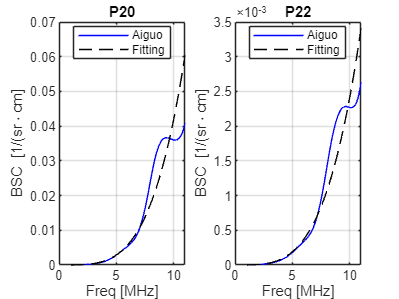

%%%%%%%%%%%%%%%%%% FITTING P22 %%%%%%%%%%%%%%%%%%



figure, 
subplot(121),
plot(freqs_P20,  bsc_P20, 'b', 'DisplayName', 'Aiguo'), 
hold on
grid on;
plot(freqs_P20,  b_P20*freqs_P20.^n_P20, 'k--', 'DisplayName', 'Fitting'), 
hold off
xlabel('Freq [MHz]'), ylabel('BSC [')
title('P20')
xlabel('Freq [MHz]'),  ylabel('BSC [1/(sr\cdotcm]')
legend('Location','best')

subplot(122),
plot(freqs_P22,  bsc_P22, 'b', 'DisplayName', 'Aiguo'), hold on
grid on;
plot(freqs_P22,  b_P22*freqs_P20.^n_P22, 'k--', 'DisplayName', 'Fitting'), hold off
title('P22')
xlabel('Freq [MHz]'),  ylabel('BSC [1/(sr\cdotcm]')
legend('Location','best')

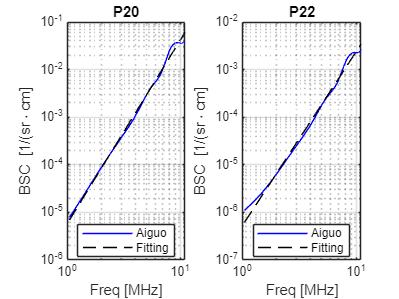



figure, 
subplot(121),
loglog(freqs_P20,  bsc_P20, 'b', 'DisplayName', 'Aiguo'), 
hold on
grid on;
loglog(freqs_P20,  b_P20*freqs_P20.^n_P20, 'k--', 'DisplayName', 'Fitting'), 
hold off
xlabel('Freq [MHz]'), ylabel('BSC [')
title('P20')
xlabel('Freq [MHz]'),  ylabel('BSC [1/(sr\cdotcm]')
legend('Location','best')

subplot(122),
loglog(freqs_P22,  bsc_P22, 'b', 'DisplayName', 'Aiguo'), hold on
grid on;
loglog(freqs_P22,  b_P22*freqs_P20.^n_P22, 'k--', 'DisplayName', 'Fitting'), hold off
title('P22')
xlabel('Freq [MHz]'),  ylabel('BSC [1/(sr\cdotcm]')
legend('Location','best')

## T7

fileNameBSC_T7 = 'rdg5292a target 7 backscatter';


pathBSC = 'C:\Users\armiz\OneDrive\Documentos\MATLAB\qus-lim';

% freqs | bsc

file_BSC_T7 = readmatrix(fullfile(pathBSC,fileNameBSC_T7)); % Freq, BSC

freqs = file_BSC_T7(:,1);
bsc   = file_BSC_T7(:,2);

%%
% Example data
% Ensure col vector
f       = freqs(:);
eta     = bsc(:);

% Transform to logarithmic scale
log_f   = log(f);
log_eta = log(eta);

% Perform linear regression
coeffs  = polyfit(log_f, log_eta, 1); % Fit y = mx + c
n       = coeffs(1); % Slope = n
ln_b    = coeffs(2); % Intercept = ln(b)

% Calculate b
b       = exp(ln_b);

% Display results
fprintf('-----T7-----\n')

-----T7-----


fprintf('n = %f\n', n);

n = 3.094201


fprintf('b = %f\n', b);

b = 0.000188


fprintf('b = %-E\n', b);

b = 1.883053E-04


fprintf('b_dB = %.2f\n', 10*log10(b))

b_dB = -37.25


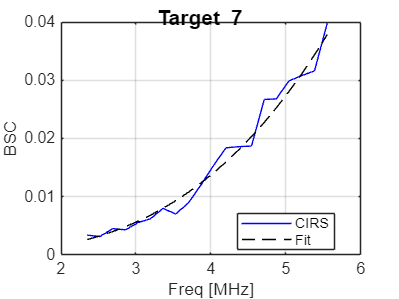


%%
figure, 
sgtitle('\bfTarget 7')
plot(freqs,  bsc, 'b', 'DisplayName', 'CIRS'), hold on
grid on;
plot(freqs,  b*f.^n, 'k--', 'DisplayName', 'Fit'), hold off
xlabel('Freq [MHz]'), ylabel('BSC')

legend('Location','best')

## BACKGROUND

fileNameBSC_bg = 'rdg5285 background backscatter.txt';


pathBSC = 'C:\Users\armiz\OneDrive\Documentos\MATLAB\qus-lim';

% freqs | bsc

file_BSC = readmatrix(fullfile(pathBSC,fileNameBSC_bg)); % Freq, BSC

freqs = file_BSC(:,1);
bsc   = file_BSC(:,2);
    
%%
% Example data
% Ensure col vector
f       = freqs(:);
eta     = bsc(:);

% Transform to logarithmic scale
log_f   = log(f);
log_eta = log(eta);

% Perform linear regression
coeffs  = polyfit(log_f, log_eta, 1); % Fit y = mx + c
n       = coeffs(1); % Slope = n
ln_b    = coeffs(2); % Intercept = ln(b)

% Calculate b
b       = exp(ln_b);

% Display results
fprintf('-----Background-----\n')

-----Background-----


fprintf('n = %f\n', n);

n = 3.446020


fprintf('b = %f\n', b);

b = 0.000008


fprintf('b = %-E\n', b);

b = 8.153915E-06


fprintf('b_dB = %.2f\n', 10*log10(b))

b_dB = -50.89


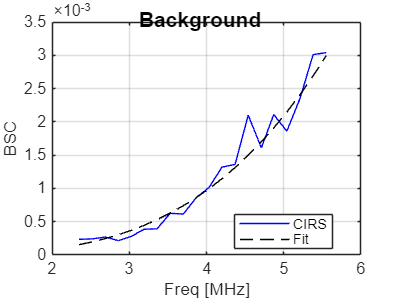


%%
figure, 
sgtitle('\bfBackground')
plot(freqs, bsc, 'b', 'DisplayName', 'CIRS'), hold on
grid on;
plot(freqs, b*f.^n, 'k--', 'DisplayName', 'Fit'), hold off
xlabel('Freq [MHz]'), ylabel('BSC')

legend('Location','best')